filelistPP = ["Position_control_PP_29-Apr-2025_15-52-56.mat", "Position_control_PP_29-Apr-2025_15-57-33.mat", "Position_control_PP_29-Apr-2025_15-59-58.mat", "Position_control_PP_29-Apr-2025_16-05-57.mat", "Position_control_PP_29-Apr-2025_16-06-47.mat", "Position_control_PP_29-Apr-2025_16-08-04.mat", "Position_control_PP_29-Apr-2025_16-15-38.mat", "Position_control_PP_29-Apr-2025_16-19-46.mat", "Position_control_PP_29-Apr-2025_16-21-40.mat", "Position_control_PP_29-Apr-2025_16-27-10.mat", "Position_control_PP_29-Apr-2025_16-42-20.mat", "Position_control_PP_29-Apr-2025_16-47-32.mat", "Position_control_PP_29-Apr-2025_16-51-46.mat", "Position_control_PP_29-Apr-2025_16-53-53.mat", "Position_control_PP_29-Apr-2025_16-56-11.mat", "Position_control_PP_29-Apr-2025_17-06-15.mat", "Position_control_PP_29-Apr-2025_17-07-34.mat", "Position_control_PP_29-Apr-2025_17-09-36.mat", "Position_control_PP_29-Apr-2025_17-12-23.mat", "Position_control_PP_29-Apr-2025_17-24-13.mat", "Position_control_PP_29-Apr-2025_17-27-12.mat", "Position_control_PP_29-Apr-2025_17-36-36.mat", "Position_control_PP_29-Apr-2025_17-44-09.mat", "Position_control_PP_29-Apr-2025_17-52-13.mat", "Position_control_PP_29-Apr-2025_17-54-56.mat", "Position_control_PP_29-Apr-2025_17-57-36.mat", "Position_control_PP_29-Apr-2025_17-59-27.mat", "Position_control_PP_29-Apr-2025_18-02-38.mat", "Position_control_PP_29-Apr-2025_18-04-42.mat", "Position_control_PP_29-Apr-2025_18-07-34.mat", "Position_control_PP_29-Apr-2025_18-09-31.mat", "Position_control_PP_29-Apr-2025_18-15-12.mat", "Position_control_PP_29-Apr-2025_18-17-45.mat", "Position_control_PP_29-Apr-2025_18-21-45.mat", "Position_control_PP_29-Apr-2025_18-22-36.mat", "Position_control_PP_29-Apr-2025_18-25-08.mat", "Position_control_PP_29-Apr-2025_18-28-11.mat", "Position_control_PP_29-Apr-2025_18-31-08.mat", "Position_control_PP_29-Apr-2025_18-34-28.mat", "Position_control_PP_29-Apr-2025_18-35-20.mat", "Position_control_PP_29-Apr-2025_18-36-40.mat", "Position_control_PP_29-Apr-2025_18-39-17.mat", "Position_control_PP_29-Apr-2025_18-49-00.mat", "Position_control_PP_29-Apr-2025_18-51-45.mat", "Position_control_PP_29-Apr-2025_18-54-05.mat", "Position_control_PP_29-Apr-2025_18-55-32.mat", "Position_control_PP_29-Apr-2025_18-57-08.mat", "Position_control_PP_29-Apr-2025_18-59-52.mat"];
filelistFB =["Angle_control_FB_29-Apr-2025_14-39-52.mat", "Angle_control_FB_29-Apr-2025_14-43-14.mat", "Angle_control_FB_29-Apr-2025_14-47-31.mat", "Angle_control_FB_29-Apr-2025_14-49-13.mat", "Angle_control_FB_29-Apr-2025_14-52-22.mat", "Angle_control_FB_29-Apr-2025_14-56-16.mat", "Angle_control_FB_29-Apr-2025_14-59-10.mat", "Angle_control_FB_29-Apr-2025_15-04-08.mat", "Angle_control_FB_29-Apr-2025_15-06-02.mat", "Angle_control_FB_29-Apr-2025_15-09-49.mat", "Angle_control_FB_29-Apr-2025_15-11-09.mat", "Angle_control_FB_29-Apr-2025_15-21-00.mat", "Angle_control_FB_29-Apr-2025_15-25-22.mat", "Angle_control_FB_29-Apr-2025_15-26-51.mat", "Angle_control_FB_29-Apr-2025_15-28-52.mat"];

m0_25deg_FB_exp = load( "lab3/data/pid/data_21-Mar-2025_10-29-46.mat").data;
m0_25deg_FB_sim = load( "lab3/out/m0_PD_25deg.mat");


m1_20deg_FB_exp = load( "lab3/data/pid/data_21-Mar-2025_10-36-06.mat").data;
m1_20deg_FB_sim = load( "lab3/out/m0_PD_20deg.mat");
 
m0_FB_exp = load("lab6/data/FB/"+filelistFB(4)).data;
m1_FB_exp = load("lab6/data/FB/"+filelistFB(5)).data;

m0_PP_LU_exp = load("lab6/data/PP/"+filelistPP(45)).data;
m1_PP_LU_exp = load("lab6/data/PP/"+filelistPP(46)).data;


m0_FB_sim = load("lab6/post/simulations/m0_PD.mat").ans;
m1_FB_sim = load("lab6/post/simulations/m1_PD.mat").ans;

m0_PP_LU_sim = load("lab6/post/simulations/m0_PP.mat").ans;
m1_PP_LU_sim = load("lab6/post/simulations/m1_PP.mat").ans;


legendFB = ["reference","experiment  FB","simulation  FB"];
legendPP = ["reference","experiment  PP:25","simulation  PP:25"];

## M0 PD

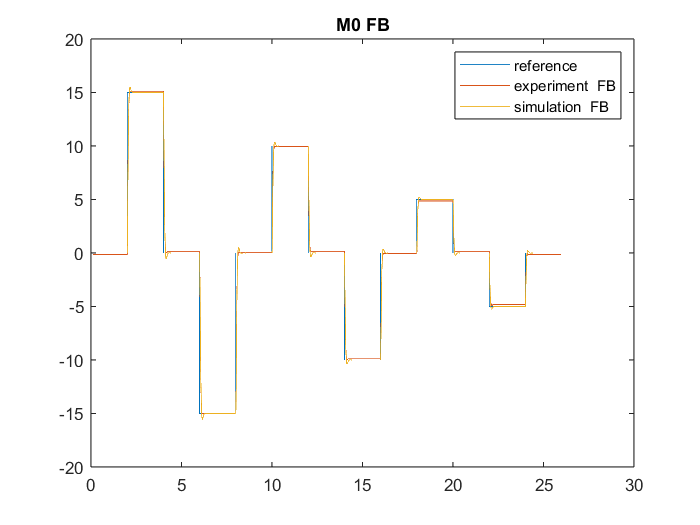

m0_FB_exp_y = rad2deg(m0_FB_exp(2,60:end))-7;
m0_FB_sim_y = rad2deg(m0_FB_sim(2,60:end));
m0_FB_sim_yref = rad2deg(m0_FB_sim(3,60:end));
t =  m0_FB_exp(1,60:end);
figure
plot(t,m0_FB_sim_yref)
hold on
plot(t,m0_FB_exp_y)
plot(t,m0_FB_sim_y)
legend(legendFB)
title("M0 FB")

## M0 PD Angle comparisons

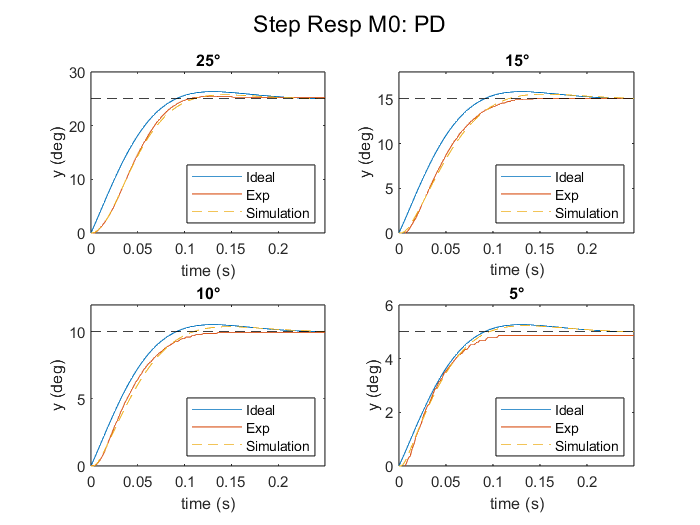

% PID0
Kp = -21.6;
Kd = -0.423;

C0 = pid(Kp,0,Kd);

dc_gain0 = -1.4479 ; % v/(rad/s)
tau0 = 1/24.9218;   % 1/s

G0 = tf([dc_gain0],[tau0 1 0]);

L0 = C0*G0;
L0d = c2d(L0,1/500);

T_pd = feedback(L0d,1);

[y_sim,tOut] = step(T_pd);
figure

t_window = 0.25;
m0_20deg_FB_y_exp = rad2deg(m0_25deg_FB_exp(2,501:501+500*t_window));
m0_20deg_FB_y_sim = (m0_25deg_FB_sim.y_sim_sat);
t_25_sim_sat = m0_25deg_FB_sim.t_sim_sat;


t_comp = 0:0.002:t_window;

subplot(2,2,1)
plot(tOut,y_sim*25)
hold on
plot(t_comp,m0_20deg_FB_y_exp)
plot(t_25_sim_sat,m0_20deg_FB_y_sim,"--")
line([0 t_window],[25 25],'Color','black','LineStyle','--')
xlim([0 t_window])
ylim([0 25*1.2])
legend(["Ideal","Exp ","Simulation"],"Location","southeast")
title("25°")
xlabel("time (s)")
ylabel("y (deg)")
sgtitle("Step Resp M0: PD")

norm_factor = [15 10 5];
for deg_exp=1:3
    t_start = 2 + (deg_exp-1)*8;
    t_start_idx = t_start*500-60 +1;
    t_end_idx = t_start_idx + t_window*500;
    subplot(2,2,deg_exp+1)
    plot(tOut,y_sim*norm_factor(deg_exp))
    hold on
    yFB_focus = m0_FB_exp_y(t_start_idx:t_end_idx);
    plot(t_comp,yFB_focus)
    yFB_sim_focus = m0_FB_sim_y(t_start_idx:t_end_idx);
    plot(t_comp,yFB_sim_focus,"--")
    
    line([0 t_window],[norm_factor(deg_exp) norm_factor(deg_exp)],'Color','black','LineStyle','--')
    legend(["Ideal","Exp ","Simulation"],"Location","southeast")
    title(norm_factor(deg_exp)+"°")
    xlabel("time (s)")
    ylabel("y (deg)")
    xlim([0 t_window])
    ylim([0 norm_factor(deg_exp)*1.2])
end


% legend(["Ideal","Exp 25°","Sim 25°","Exp 15°","Sim 10°","Exp 10°","Sim 10°","Exp 5°","Sim 5°",],"Location","southeast")
% 

## M0 PP+Lu

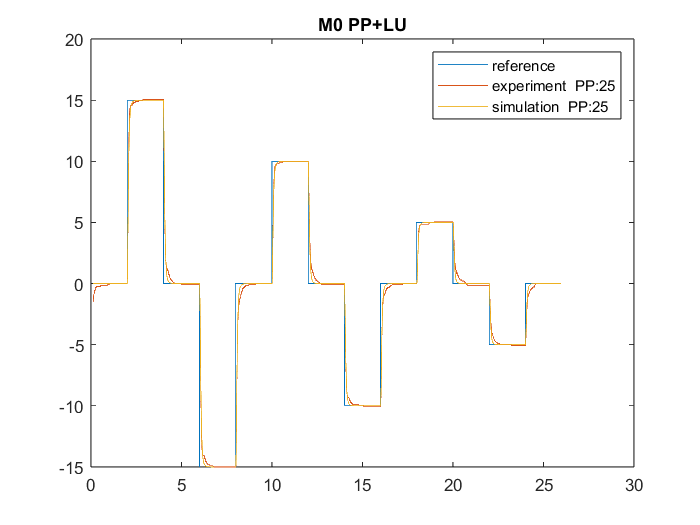



m0_PP_LU_exp_y = rad2deg(m0_PP_LU_exp(2,60:end))-7;
m0_PP_LU_sim_y = rad2deg(m0_PP_LU_sim(2,60:end));
m0_PP_LU_sim_yref = rad2deg(m0_PP_LU_sim(3,60:end));
t =  m0_PP_LU_exp(1,60:end);
figure
plot(t,m0_PP_LU_sim_yref)
hold on
plot(t,m0_PP_LU_exp_y)
plot(t,m0_PP_LU_sim_y)
legend(legendPP)
title("M0 PP+LU")

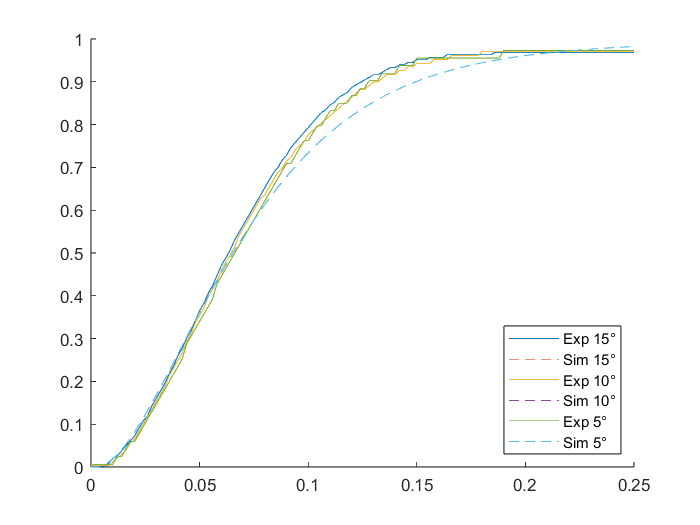


% PID0
Kp = -21.6;
Kd = -0.423;

C0 = pid(Kp,0,Kd);

dc_gain0 = -1.4479 ; % v/(rad/s)
tau0 = 1/24.9218;   % 1/s

G0 = tf([dc_gain0],[tau0 1 0]);

L0 = C0*G0;
L0d = c2d(L0,1/500);

T_pd = feedback(L0d,1);

[y_sim,tOut] = step(T_pd);
figure

t_window = 0.25;
m0_20deg_FB_y_exp = rad2deg(m0_25deg_FB_exp(2,501:501+500*t_window));
m0_20deg_FB_y_sim = (m0_25deg_FB_sim.y_sim_sat);
t_25_sim_sat = m0_25deg_FB_sim.t_sim_sat;


t_comp = 0:0.002:t_window;

subplot(2,2,1)
plot(tOut,y_sim*25)
hold on
plot(t_comp,m0_20deg_FB_y_exp)
plot(t_25_sim_sat,m0_20deg_FB_y_sim,"--")
line([0 t_window],[25 25],'Color','black','LineStyle','--')
xlim([0 t_window])
ylim([0 25*1.2])
legend(["Ideal","Exp ","Simulation"],"Location","southeast")
title("25°")
xlabel("time (s)")
ylabel("y (deg)")
sgtitle("Step Resp M0: PD")

norm_factor = [15 10 5];
for deg_exp=1:3
    t_start = 2 + (deg_exp-1)*8;
    t_start_idx = t_start*500-60 +1;
    t_end_idx = t_start_idx + t_window*500;
    subplot(2,2,deg_exp+1)
    plot(tOut,y_sim*norm_factor(deg_exp))
    hold on
    yFB_focus = m0_FB_exp_y(t_start_idx:t_end_idx);
    plot(t_comp,yFB_focus)
    yFB_sim_focus = m0_FB_sim_y(t_start_idx:t_end_idx);
    plot(t_comp,yFB_sim_focus,"--")
    
    line([0 t_window],[norm_factor(deg_exp) norm_factor(deg_exp)],'Color','black','LineStyle','--')
    legend(["Ideal","Exp ","Simulation"],"Location","southeast")
    title(norm_factor(deg_exp)+"°")
    xlabel("time (s)")
    ylabel("y (deg)")
    xlim([0 t_window])
    ylim([0 norm_factor(deg_exp)*1.2])
end

## M1 PD

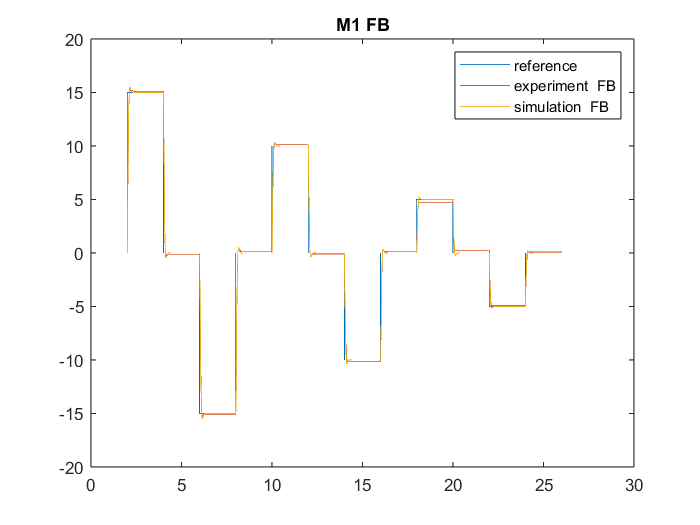

m1_FB_exp_y = rad2deg(m1_FB_exp(3,60:end))-0;
m1_FB_sim_y = rad2deg(m1_FB_sim(2,60:end));
m1_FB_sim_yref = rad2deg(m0_FB_sim(3,60:end));
t =  m1_FB_exp(1,60:end);
figure
plot(t,m1_FB_sim_yref)
hold on
plot(t,m1_FB_exp_y)
plot(t,m1_FB_sim_y)
legend(legendFB)
title("M1 FB")

## M1 PP+Lu

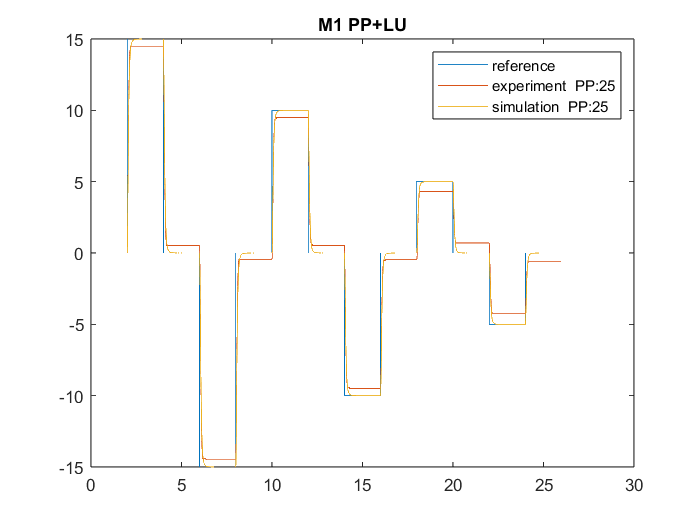



m1_PP_LU_exp_y = rad2deg(m1_PP_LU_exp(3,60:end))-0;
m1_PP_LU_sim_y = rad2deg(m1_PP_LU_sim(2,60:end));
m1_PP_LU_sim_yref = rad2deg(m1_PP_LU_exp(11,60:end));
t =  m1_PP_LU_exp(1,60:end);
figure
plot(t,m1_PP_LU_sim_yref)
hold on
plot(t,m1_PP_LU_exp_y)
plot(t,m1_PP_LU_sim_y)
legend(legendPP)
title("M1 PP+LU")

warning("Repeat pole placement experiments for M1")